# Linear Control Design 2 - Fall 2023 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E23) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E23'
Student_Name = 'Student Name'
Student_Number = 'Student Number'

## Missile autopilot - Problem description

Consider the missile airframe control problem illustrated in the Figure below. When the missile is flying with an angle of attack $\alpha$, lift is developed. This lift may be represented as acting at a central location, called the centre of pressure. The missile is stable or unstable (without corrective tail deflections) depending on the location of the centre of presure relative to the centre of mass. The control problem requires that the autopilot generates the required tail deflection $\delta$ to produce an angle of attack corresponding to the desired manoeuvre, while stabilizing the airframe rotational motion.

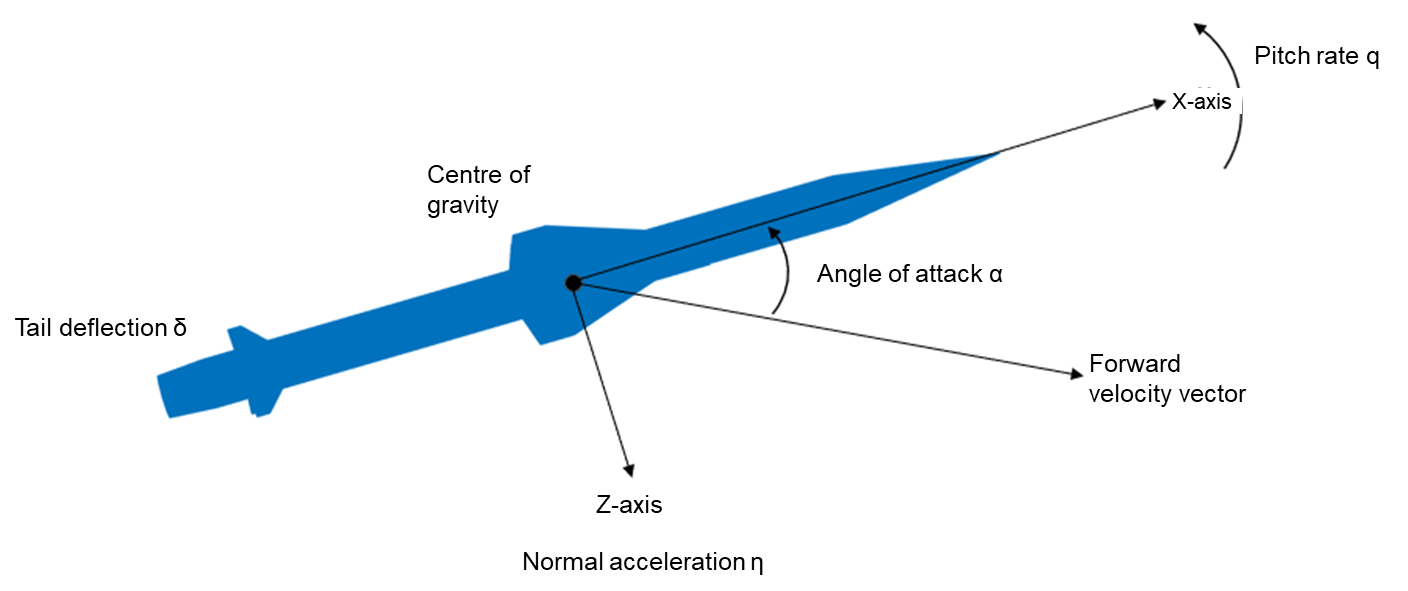

Sensor measurements for feedback include missile rotation rates from rate gyros, and normal acceleration from accelerometers. Typical uncertainties to be considered in this control problem include: aerodynamic characteristics, mass and balance, wind, flexible mode dynamics, actuator and sensor nonlinearities, and sensor noise.

We wish to design an autopilot to track commended normal acceleration manoeuvres with a steady state accuracy of 0.5% and a time constant of less than 0.2 seconds.

### Missile nonlinear dynamical model

The nonlinear state equations for this control problem are given by


$$\dot{\alpha} = K_\alpha M C_n(\alpha,\delta, M)\cos\alpha + q \\
\dot{q} = K_q M^2 C_m(\alpha,\delta, M) \\
y_1 = \eta = K_z M^2 C_n(\alpha,\delta, M) \\
y_2 = q
 $$


where the aerodynamic coefficients $C_n(\alpha,\delta, M)$ and $C_m(\alpha,\delta, M)$ are given by


$$C_n(\alpha,\delta, M) = \mathrm{sgn}(\alpha)[a_n |\alpha|^3 + b_n |\alpha|^2 + c_n(2-M/3) |\alpha|] + d_n \delta \\
C_m(\alpha,\delta, M) = \mathrm{sgn}(\alpha)[a_m |\alpha|^3 + b_m |\alpha|^2 + c_m(-7+8M/3) |\alpha|] + d_m \delta$$


and the function $\mathrm{sgn}(\alpha)$ is the signum function, i.e. $\mathrm{sgn}(\alpha) = 1 $ if $\alpha >0$; $\mathrm{sgn}(\alpha) = -1 $ if $\alpha <0$; $\mathrm{sgn}(\alpha) = 0$ if $\alpha =0$. In the model above the relevant quantities are so defined

- $\alpha$ is the angle of attack in degrees

- $q$ is the pitch rate in degree per second

- $M$ is the Mach number

- $\delta$ is the tail deflection angle in degrees

- $\eta$ is the normal acceleration in $g$'s, where $g$ is the acceleration of gravity

The nonlinear model is implemented in the Simulink file pitch_axix_missile_nonlinear_model_SimulinkYYYYC, where YYYYC refers to the Simulink version (2022b, 2022a, 2021b, etc.). The numerical values for the model parameters are provided right below.

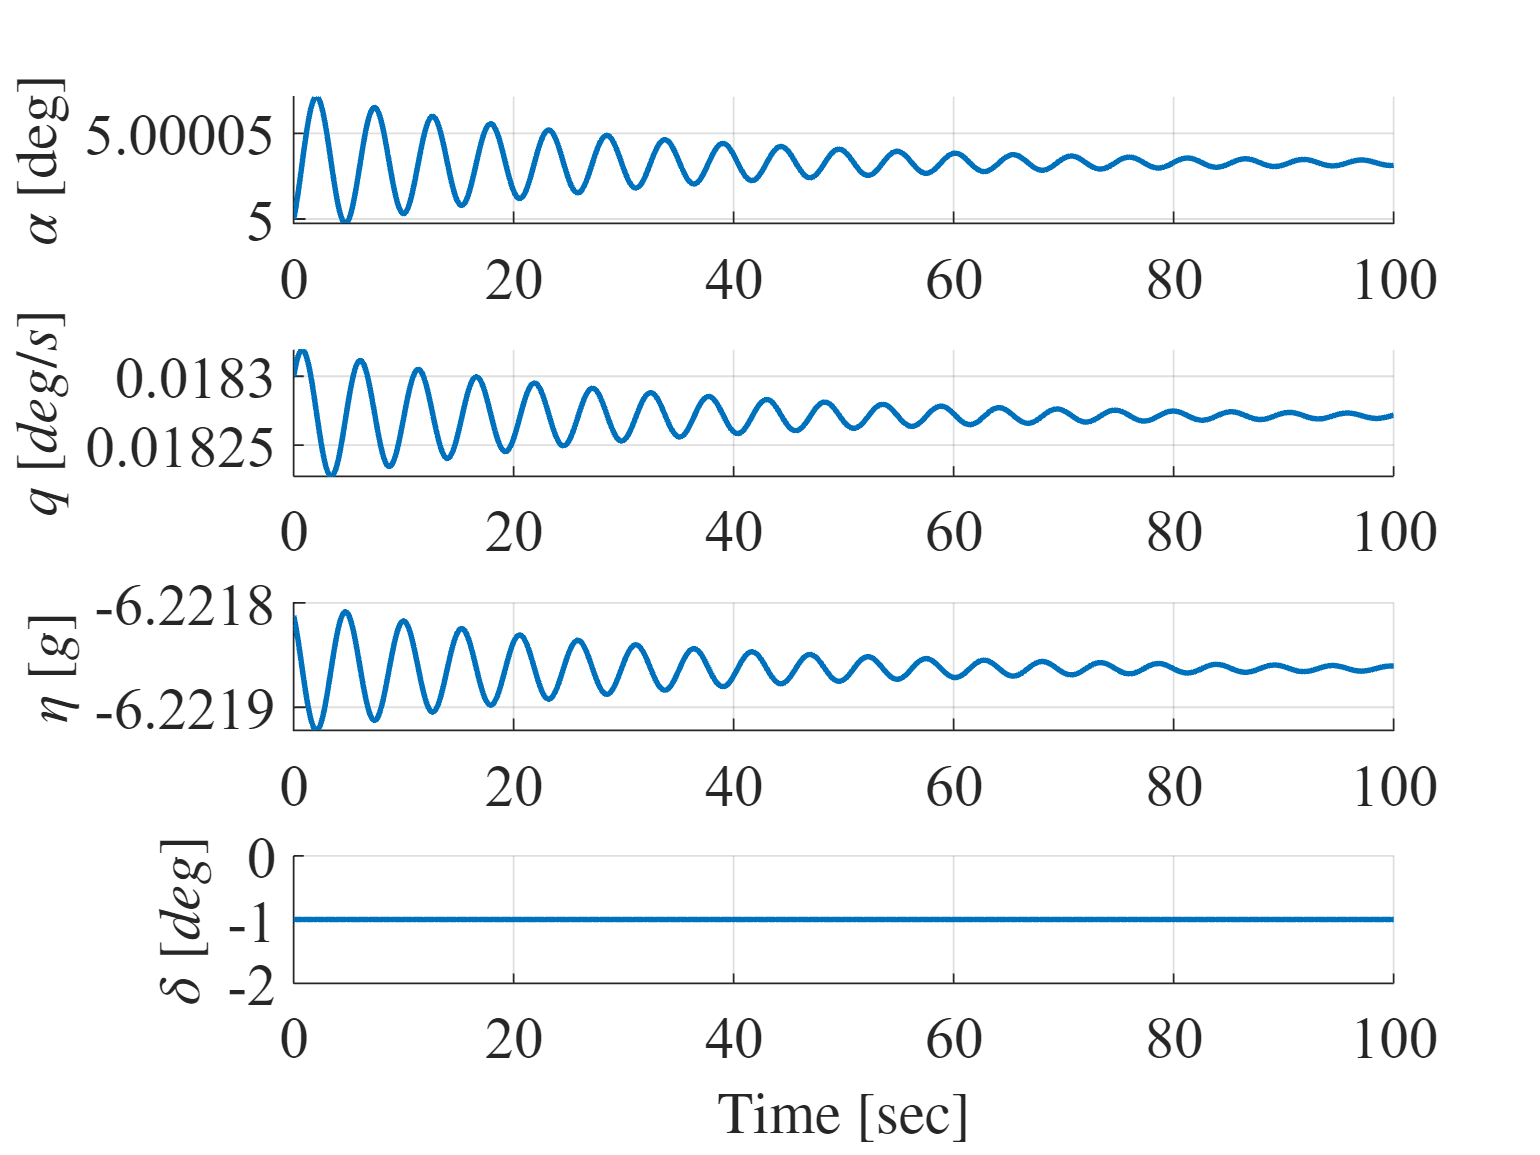

% Simulator parameters (RG)
SIM_TIME = 100; % simulation time (can be changed as needed)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'pitch_axis_missile_nonlinear_model_Simulink2022b';

% Model paramters (RG)
P0 = 46601.86; % Static pressure at 6096 m [Pa]
S = 0.04088; % surface area [m^2]
m = 204; % mass [kg]
v_s = 315.9; % speed of sound at 6096 m [m/s]
d = 0.2286; % diameter [m]
Iy = 247.44; % pitch moment of inertia [kg*m^2]
K_alpha = 0.7*P0*S/(m*v_s); % [1/s]
K_q = 0.7*P0*S*d/Iy; % [1/s^2]
K_z = 0.7*P0*S/m; % [m/s^2]
M = 3; % Mach number
a_n = 0.000103; % [1/deg^3]
b_n = -0.00945; % [1/deg^2] 
c_n = -0.1696; % [1/deg]
d_n = -0.034; % [1/deg]
a_m = 0.000215; % [1/deg^3]
b_m = -0.0195; % [1/deg^2]
c_m = 0.051; % [1/deg]
d_m = -0.206; % [1/deg]
g = 9.81; % gravity constant [m/s^2]

% Test the provided nonlinear model (RG)
time = (0:STEP_SIZE:SIM_TIME)';
x0 = [5,0.0183]'; % initial condition x0 = [alpha,q]'
delta = -0.9982; % tail deflection angle [deg]
U = delta*ones(length(time),1); % controllable input
simOut = sim(SIMULINK_FILENAME,SIM_TIME,[],[time U]);

% Plot temporal behaviour of the state of the nonlinear model (RG)
alpha = simOut.logsout.getElement(1).Values.Data;
q = simOut.logsout.getElement(2).Values.Data;
eta = simOut.logsout.getElement(3).Values.Data/g; % normalize by the gravity constant to obtain the normal acceleration in g's

figure, h1 = subplot(4,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,alpha,'LineWidth',1.5)
ylabel('$\alpha$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(4,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,q,'LineWidth',1.5)
ylabel('$q$ [$deg/s$]','FontName','times','FontSize',16,'Interpreter','latex')
h3 = subplot(4,1,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(time,eta,'LineWidth',1.5)
ylabel('$\eta$ [$g$]','FontName','times','FontSize',16,'Interpreter','latex')
h4 = subplot(4,1,4); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(time,U,'LineWidth',1.5)
ylabel('$\delta$ [$deg$]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

## Operating point and linearization

**Problem 1 [2 points] **Numerically determine the stationary point associated with the angle of attack $\alpha = 10 \,\mathrm{deg}$, and then linearize the system around the stationary point $(\mathbf{x}_{ss},\mathbf{u}_{ss},\mathbf{y}_{ss},)$, where the subscript "ss" stands for stationary state.

% Your solution goes here


## Stability analysis

**Problem 2 [2 points]** Assess the internal stability of the linear system and graphically show the eigenmodes of the system.

% Your solution goes here


## Design of autopilot for tracking commanded normal acceleration manoeuvres

The control objective is to design an autopilot to track commanded normal acceleration manoeuvres, while stabilizing the airframe pitch motion. Given a commanded step change of normal acceleration of $\pm1g$, the design autopilot must fulfill the followingwith a steady state accuracy of 0.5% and a time constant of less than 0.2 seconds.

Closed-loop system requirements

1) The steady state error $e_\eta = \eta_c - \eta$ is less than 0.5%, where $\eta_c$ is the commanded normal acceleration.

2) The settling time is less than or equal to 1 second

3) The tail angular deflection does not exceed 25 degrees, i.e. $|\delta| \leq 25\, \mathrm{deg}$

**Problem 3 [4 points]** Under the assumption that the state is fully accessible design a discrete time controller that meets the aforementioned specifications on the nonlinear system using the eigenstructure assignment method.

% Your solution goes here


**Problem 4 [2 points]** Verify your design through simulation on the linear and nonlinear model, and discuss to which degree the control requirements are fulfilled.

% Your solution goes here


## Kalman filtering for output feedback control

The angle of attack $\alpha$ is not measured, therefore the designed autopilot cannot be implemented unless the state vector is estimated based on the available measurements. Now, we assume that the accelerometer and the rate gyro are affected by white noise, i.e.


$$y_1 = \eta +\nu_\eta \\
y_2 = q + \nu_q$$


where $\nu_\eta$ is zero mean white noise with amplitude $A_{\nu_\eta} = \pm 0.003\, \mathrm{m}/\mathrm{s}^2$, and $\nu_q$ is zero mean white noise with amplitude $A_{\nu_q} = \pm 0.006\,\mathrm{deg}/\mathrm{s}$.

**Problem 5 [4 points]** Design a discrete time Kalman filter to estimate the state vector $\mathbf{x} = [\alpha,q]^T$ and the measured output $y_1 = \eta$. 

% Your solution goes here


**Problem 5 [4 points] **Assess the estimation performance of the Kalman filter when tested on the closed loop nonlinear system for commanded step changes of normal acceleration of $\pm1g$.

% Your solution goes here
